Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" ([https://www.crcpress.com/9781138589940](https://www.crcpress.com/9781138589940))

# C-magnet, the upper half (Section 4.3.2)

Volker Ziemann, 211109, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

This example deals with the same magnet as Cmagnet.mlx, but now we exploit the fact the the lower half of the magnet is a mirror image of the upper half and we therefore only need to define the geometry for the upper half, but have to define appropriate boundary conditions in he mid-plane.

Let's define the geomtry first, Now the polygon for the` yoke` has fewer points and we only have to describe the two coils `C1` and `C2` in the ipper half and, as before, the `World` as enclosing volume. 

clear all;  close all
Cmag=[2; 8; ...    %..Yoke
    0;0;0.3;0.3;1;1;-0.6;-0.6; ...    % eigth x-ccordinates
    0;0.3;0.3;0.05;0.05;0.8;0.8;0];   % eigth y-coordinates
C1=[2;4;0;0;0.3;0.3;  0.1;0.3;0.3;0.1;zeros(8,1)];  % add zeros to make same 
C2=[2;4;1;1;1.3;1.3;  0.1;0.3;0.3;0.1;zeros(8,1)];  % length as yoke
World=[2;4; -1;1.6;1.6;-1;0;0;1;1;zeros(8,1)]; 
gd=[World,Cmag,C1,C2];  % assemble geometry
ns=char('World','Cmag','C1','C2')';  % names of the regions                 
sf='World+Cmag+C1+C2'; 
g=decsg(gd,sf,ns);

In the next step we create the PDE model for one dynamic variable` u =` $A_z$, add the geometry `g` to the model, and plot the model with the edges labeled. As in the pervious example with the full-scale magnet, we require the potential $A_z$ to vanish at the outer boundaries, lebeled `E1, E2,` and `E3`. In the second call to applyBoundaryCondition() on `E8, E9,` and `E10,` we specify von-Neumann boundary conditions, which ensures that the fields are perpendicular to the boundary. This enforces the up-down symmetry of the full magnet.

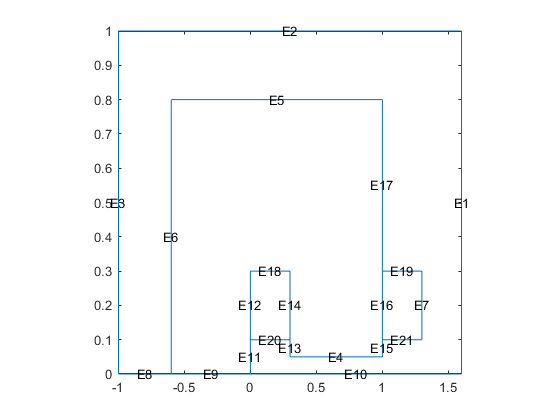

model=createpde(1);
geometryFromEdges(model,g);
pdegplot(model,'EdgeLabels','on');axis square 

applyBoundaryCondition(model,'Edge',[1:3],'u',0);          % Dirichlet
applyBoundaryCondition(model,'Edge',[8:10],'q',0,'g',0);   % von-Neumann

Now we plot the geometry with the SubDomainLabels in order to be able to specify the material properties in the respective regions, which is essentially unchanged from the example with the full-scale magnet.

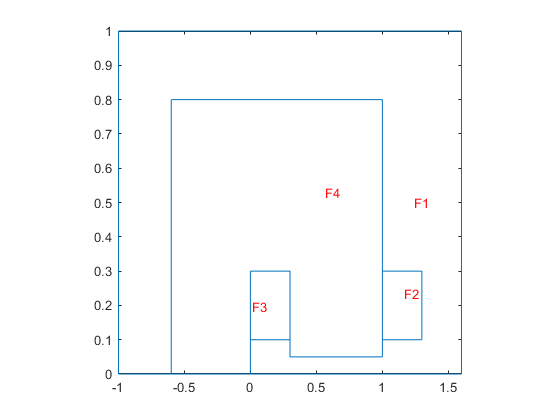

figure;
pdegplot(model,'SubDomainLabels','on');
axis square 

specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0,'Face',1);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',-0.8378,'Face',2);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0.8378,'Face',3);
specifyCoefficients(model,'m',0,'d',0,'c',1/5000,'a',0,'f',0,'Face',4);

Having specified all boundaries and materials, we can mesh the geometry.

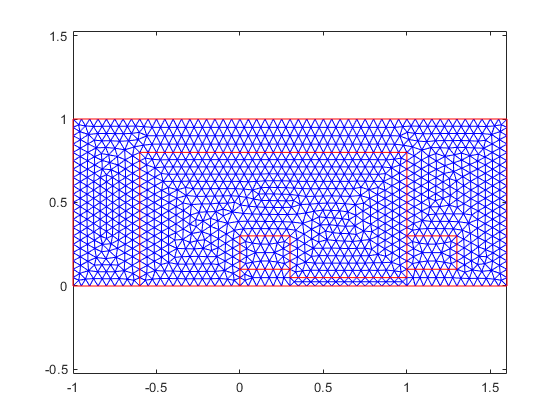

generateMesh(model,'Hmax',0.05); 
figure; 
pdemesh(model);

and solve for the potential ` u =` $A_z$ with a call to `solvepde()` before plotting` u, `which is available as member` NodalSolution` in the structure` result`.

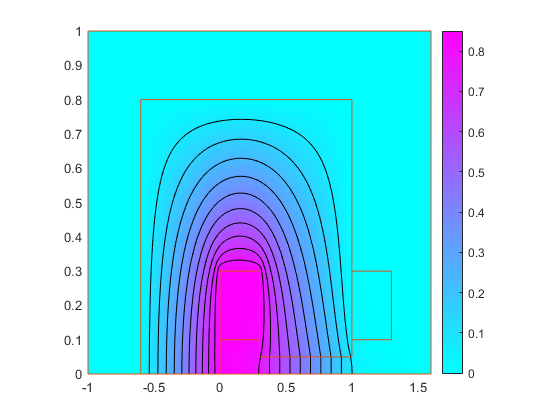

result=solvepde(model);
figure; pdeplot(model,'xydata',result.NodalSolution,'contour','on'); %axis equal
hold on; pdegplot(model); axis square

Now we post-process the result by calculating the gradients and calculating the magnitude of the field `Bn`, which we also plot.

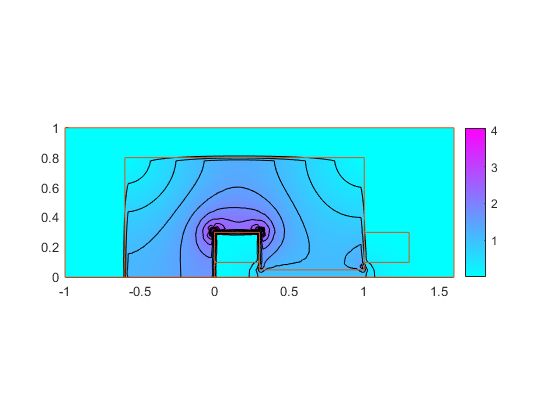

Bn=hypot(result.XGradients,result.YGradients);
figure; pdeplot(model,'xydata',Bn,'contour','on'); 
hold on; pdegplot(model);

The last plot shows the magnitude of the field` Bn` along a line, specified by` x` and` y` in the mid-plane of the magnet gap.

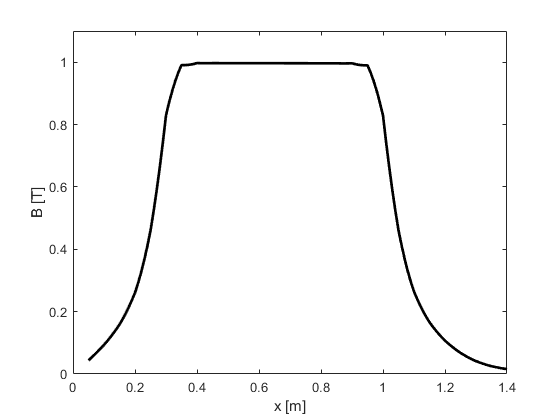

x=0.05:0.01:1.4; y=zeros(1,length(x));
[By,Bx]=evaluateGradient(result,x,y);  Bx=-Bx;
B=hypot(Bx,By);
figure; plot(x,B,'k','LineWidth',2)
xlabel('x [m]'); ylabel('B [T]'); ylim([0,1.1]); 

That's it for now.